# Chapter 4: Friedkin-Johnsen model

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

## 4.1 Friedkin-Johnsen model

This model introduced a discrete-time modification of the dynamics [M3.2](matlab:open('./ch03_taylor.mlx')). This model has been experimentally validated for small and medium-size groups.

Similar to DeGroot's dynamics [M1.1](matlab:open('./ch01_fdg.mlx')), the Friedkin-Johnsen model employs a stochastic matrix of social infleunces $W$, corresponding to the influence graph $\mathcal G[W]$. 

Beside this matrix, a diagonal matrix $\Lambda = diag(\lambda_1, \dots, \lambda_n)$ is introduced, where $\lambda_i \in [0,1]$ stands for the susceptibility of agent $i$ to the process of social influence. 

The vector of the agents' opinion evolves in accordance with 

                                                                            (M4.1)$x(k+1) = \Lambda W x(k) + (I-\Lambda)u$

Here $u$ is a constant vecotr of the agents' prejudices. 

The susceptibilities' complements $1-\lambda_i$ play the same role as the coefficients $\gamma_i$ in model [M3.2](matlab:open('./ch03_taylor.mlx')).

- $\Lambda = 0$ the model M4.1turns into the French-DeGroot model [M1.1](matlab:open('./ch01_fdg.mlx'))

- If $1-\lambda_i=0$ then agent $i$ is independent of the prejudice vector $u$ and applies the usual French-DeGroot rule

- When $\lambda_i<1$ agent i is anchored to its prejudice $u_i$ and factors its intro any opinion iteration.

- If $\lambda_i =0$ then the $i$-th agents' opinion stabilizes at the first tep $x_i(k) \equiv u_i \ \forall k \ge 1$; such an agent is stubborn $x_i(k) \equiv x_i(0)$ when $u_i \equiv x_i(0)$

In the Friedking-Johnsen theory it is supposed traditionally that $u 0 x(0)$, ie the prejudices of the agents are their initial opinions. This assumption motivates to adopt the "coupling condition" $1-\lambda_i = w_{ii}$ stating that the levels of agent's anchorage to the initial opinions are determined by their self-confidence weights. At the same time the prejudice may be independet of the initial opinion, for this reason we do not adopt these coupling conditions in this tutorial.

## 4.2 Convergence and stability conditions

We call agent $i$ **prejudiced** if $\lambda_i<1$, ie the prjudice $u_i$ influences its opinion at each step $k$

We split agents in two classes:

- Agent $i$ is said to be **P-dependent **(prejudice dependent, for simplicity **PD**) if is either prejudiced or influenced by some prejudiced agent $j$ (ie: a walk from $j$ to $i$ exists in the graph $\mathcal G [A]$).

- Agent i is said to be **P-independent **(for simplicity **PI**) otherwise.

Assume agents $1, \dots,r\ge 1$ are PD and agents $r+1,\dots,n$ are PI (possibly $r=n$). Denote the corresponding parts of the opinion vecotr by, respectively, $x_1(t)\in\mathbb R^r$ and $x_2(t)\in\mathbb R^{n-r}$. 

Since PD agents are, by definition, not prejudiced ($\lambda_i = 1$), then  M4.1 is decomposed as

                                                        (M4.1.1)$x_1(k+1) = \Lambda^{11}[W^{11}-x_1(k)+W^{12}x_2(k)]-(I-\Lambda^{11})u_1$

                                                                                (M4.1.2)$x_2(k+1) = W^{22}x_2(k)
$

The matrix $W^{22}$ is a stochastic matrix, ie the PI agents obey the French-DeGroot model.

**Theorem 4.1 **Let the community have $r\ge1$ PD agents and $n-r\ge0$ PI ones. Then the subsystem M4.1.1 is asymptotically stable, ie $\Lambda^{11}W^{11}$ is Schur stable $\rho(\Lambda^{11}W^{11})<1$. The model M4.1 is convergent $\iff$ $r=n$ or M4.1.2 is convergent, ie $W^{22}$ is regular. In this case:

                                                                            (E4.1)    $x^1(\infty) = V[u^1, x^2(\infty)]^T \\
V \triangleq (I_r -\Lambda^{11}W^{11})^{-1}[I_r-\Lambda^{11}, \ \Lambda^{11}W^{12}]$

The matrix $V$is stochastic, ie the final opinion of any agent is a convex combination of the prejudices and final opinions of PI agents.

**Corollary 4.1 **The Friedkin-Johnsen model M4.1 is asymptotically stable $\iff$ all agents are PD. Then $V = (I- \Lambda W)^{-1}(I-\Lambda)$. This holds, in particular, if $\Lambda < I_n$ or $\Lambda \neq I_n$ and $\mathcal G[W]$ is strongly connected ( $W$ is irreducibile).

**Corollary 4.2 **The model M4.1 converges $\iff$ $A = \Lambda W$ is regular, ie the limit $\lim_{k \rightarrow \infty}A^k$ exists

% esempio 3 del paper

## 4.3 Friedkin's influence centrality and PageRank

A natural question arises whether the concept of social power can be extended to model M4.1. Such extension will be based on the equality E4.1. We confine ourselves to the case of asymptotically stable model M4.1 with the prejudice vector $u = x(0)$, hence $x(\infty) = Vx(0)$ where $V = (I - \Lambda W)^{-1}(I-\Lambda)$.

French's social power assumed that the angets converge to the same consensu opinion $x_1(\infty) = \dots = x_n(\infty)$; the social power of agent $i$ is defined as the weight of its initial opinion $x_i(0)$ in this final opinion of the group.

FJ models provides a generalization of social power of agent $i$ as the mean weight of its initial opinion in determining group members' final opinions. Mathematically, these mean infleunce wieghts are elements of the non-negative vector $c \triangleq n^{-1}V^T\mathbb 1_n$, which satisfies the following equality

                                                                        (E4.2)$\bar x = \frac1n\sum^n_{i=1} x_i(\infty) = \frac1n \mathbb 1_n^TVx(0) = c^Tx(0)$

We call $c_i$ the *influence centrality *of agent $i$. Since $V$ is stochastic, $c^T \mathbb 1_n=1$. 

Similar to French's social power, the influence centrality is generated by an opinion formation mechanism. Choosing a stochastic matrix $W$, adapted to  given graph $\mathcal G$ with $n$ nodes, and some diagonal matrix $\Lambda$, Friedkin's construction gives a very insightful and broad class of centrality measures. 

For a fixed $W$, let $\Lambda = \alpha I_n$ with $\alpha \in (0,1)$ and consider the corresponding matrix $V_\alpha$ and vector $c_\alpha$. Obviously, $c_0 = n^{-1}\mathbb 1_n$, ie the social power is uniformly distributed between all the agents. As $\alpha \rightarrow 1$, the vector $c_\alpha$ converges to French's social power (when it exists).

**Lemma 4.1 **Let $W$ be a fully regular matrix and $p_\infty$ stand for the vector of French's social power, corresponding to the model  [M1.1](matlab:open('./ch01_fdg.mlx')). Then $p_\infty = \lim_{\alpha \rightarrow 1-0}c_\alpha$

Indeed $V_\alpha = (1-\alpha)(I-\alpha W)^{-1}\rightarrow W^\infty$ for $\alpha \rightarrow 1^-$, where $W^\infty = \lim_{k \rightarrow \infty}W^k = \mathbb 1_np^T$. Thus $c_\alpha = n^{-1}V_\alpha^T\mathbb 1_n \rightarrow p_\infty$ for $\alpha \rightarrow 1^-$.

The class of Friedkin's centrality measures $f_\alpha$ contains the well-known PageRank. The relation between the influence centrality and PageRank follows from the contruction of PageRank via random surfing.

Consider a segment of WWW with $n$ web pages and a stochastic $n\times n$ hyperlink matrix $W=(w_{ij})$, where $w_{ij}>0$ $\iff$ a hyperlink leads from the i-th webpage to the j-th one. Such weight represents the probability to choose hyperlink to webpage $j$ from webpage $i$

Random surfing is a Markov process; denoting the probability to open webpage $i$ on step $k$ by $p_i(k)$, the row vector $p(k)^T = (p_1(k),\dots, p_n(k))$ obeys the dual FDG (TODO: MANCA LINLK CON FDG PERCHé NON HO FATTO BENE QUELLA PARTE).

If the French social power vector $p_\infty$ is well-defined, then the probability distribution $p(k)$ converges to $p_\infty$. Since $p_\infty^T = p^TW$, the vector $p_\infty$ satisfies the natural principle of webpage ranking: a webpage referred by highly ranked webpages should also get a high rank. However, the web graphs are often disconnected, so $W$may be not fully regular, ie the French's social power may not exist. To avoid this problem, the Markov process of random surfing is modified, allowing the teleportation from each node to a randomly chosen webpage. 

With probability $m\in(0,1)$, at each step the surfer "gets tired" and opens a random webpage, sampled from the uniform distribution. The Markov Chain (QUELLA DI FDG MANCANTE) is replaced by 

                                                                        (M4.2)$p(k+1)^T = (1-m)p(k)^TW+\frac mn \mathbb 1_n^T
$

which is dual to the FJ model M4.1 with $\Lambda = (1-m)I_n$. 

It can be easily shown  that $p(k)^T \rightarrow c^T_{1-m} = \frac mn \mathbb 1_n^T(1-(1-m)W)^{-1}$, since is a special case of Friedkin's influence centrality, this limit probability is referred to as PageRank (Google algorithm used $m=0.15$).

## 4.4 Alternative interpretations and extensions

## 4.5 Examples

Three examples. The first puts the model beside French-DeGroot and then studies the effect of the susceptibility on its own; the second makes the decomposition of section 4.2 visible and shows what decides convergence; the third builds the influence centrality of section 4.3 and arrives at PageRank. Throughout the prejudices are the initial opinions, u = x(0).

N  = 6;
x0 = [3; -1; 5; 0; 2; -2];
u  = x0;

fprintf('N = %d agents,  u = x(0)\n', N);

N = 6 agents,  u = x(0)


## 4.5.1 The effect of the susceptibility

The directed cycle is the topology on which French-DeGroot never settles: strongly connected but of period 6, so all six eigenvalues of W lie on the unit circle and the opinions rotate forever. Corollary 4.1 says that with Lambda different from I and W strongly connected the model becomes asymptotically stable.

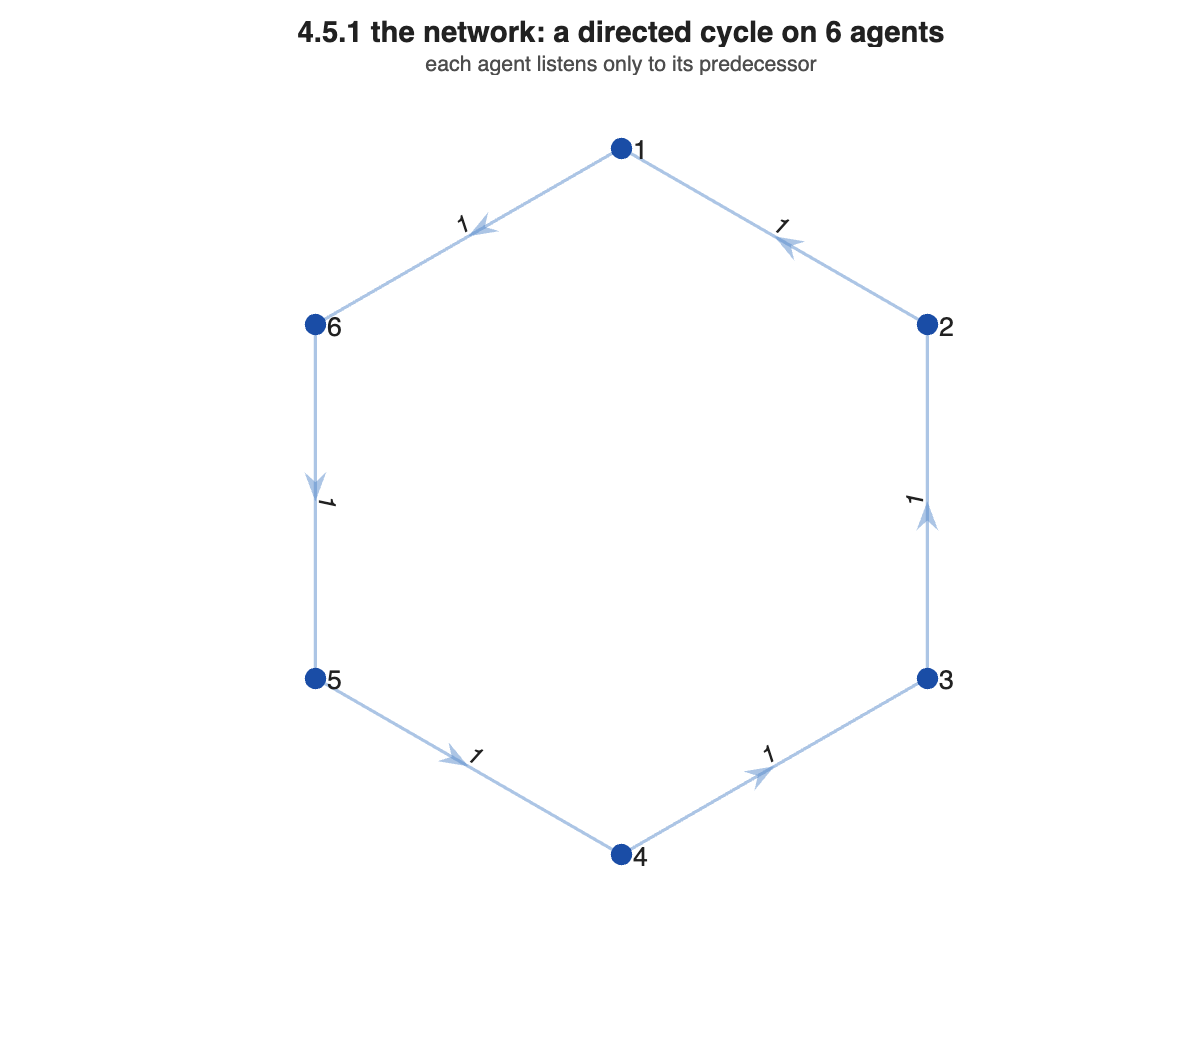

W = row_stochastic(ring_graph(N));

figure('Position',[0 0 600 520]);
plot_graph(W, [], 'Title','4.5.1 the network: a directed cycle on 6 agents', ...
    'Subtitle','each agent listens only to its predecessor')

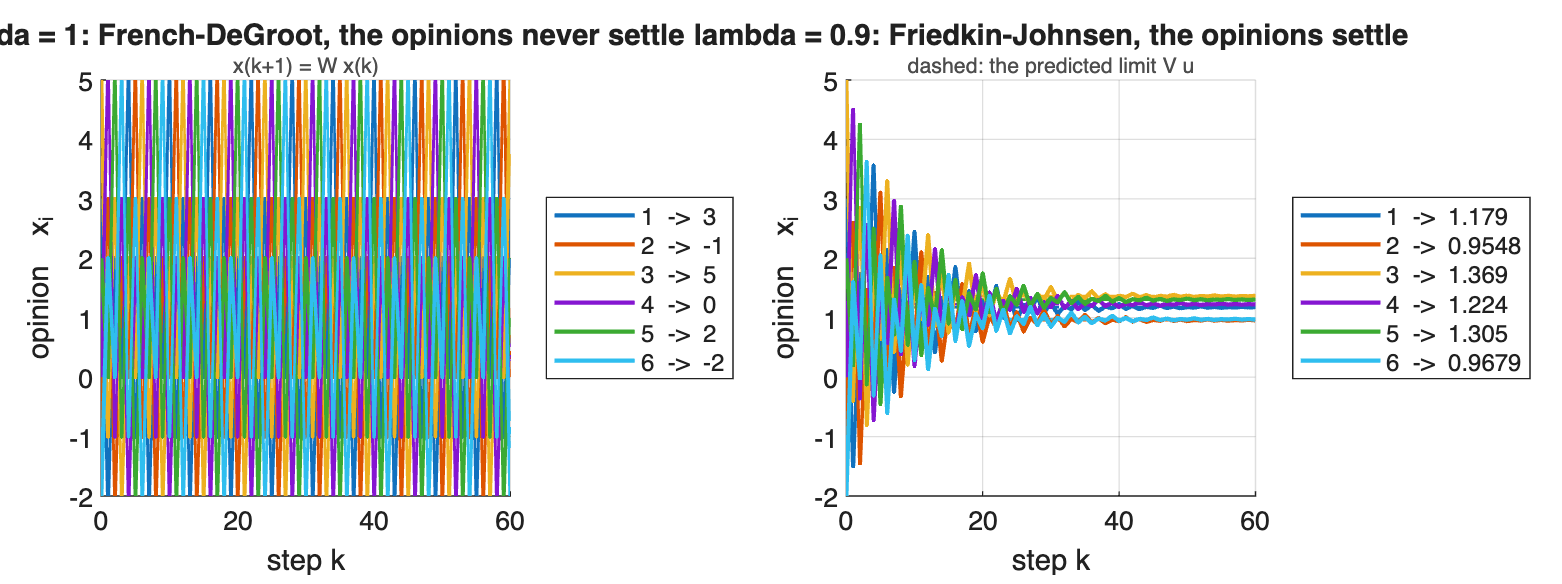

lam0 = 0.9;
Xfdg = sim_degroot(W, x0, 60);
Xfj  = sim_friedkin_johnsen(W, lam0*ones(N,1), u, x0, 60);

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_opinions(Xfdg, [], 'Title','lambda = 1: French-DeGroot, the opinions never settle', ...
    'Subtitle','x(k+1) = W x(k)');
nexttile;
plot_opinions(Xfj, [], 'Limit', total_influence(W, lam0*ones(N,1))*u, ...
    'Title','lambda = 0.9: Friedkin-Johnsen, the opinions settle', ...
    'Subtitle','dashed: the predicted limit V u');

Everything that follows isolates the susceptibility. Because Lambda = lambda I, the matrix Lambda W is simply lambda W, so its eigenvalues are those of W scaled towards the origin by exactly lambda. Sweeping lambda from 1 down to 0 in steps of 0.1 makes that motion visible: the six eigenvalues sit on the unit circle at lambda = 1 and collapse to a single point of multiplicity 6 at the origin when lambda = 0.

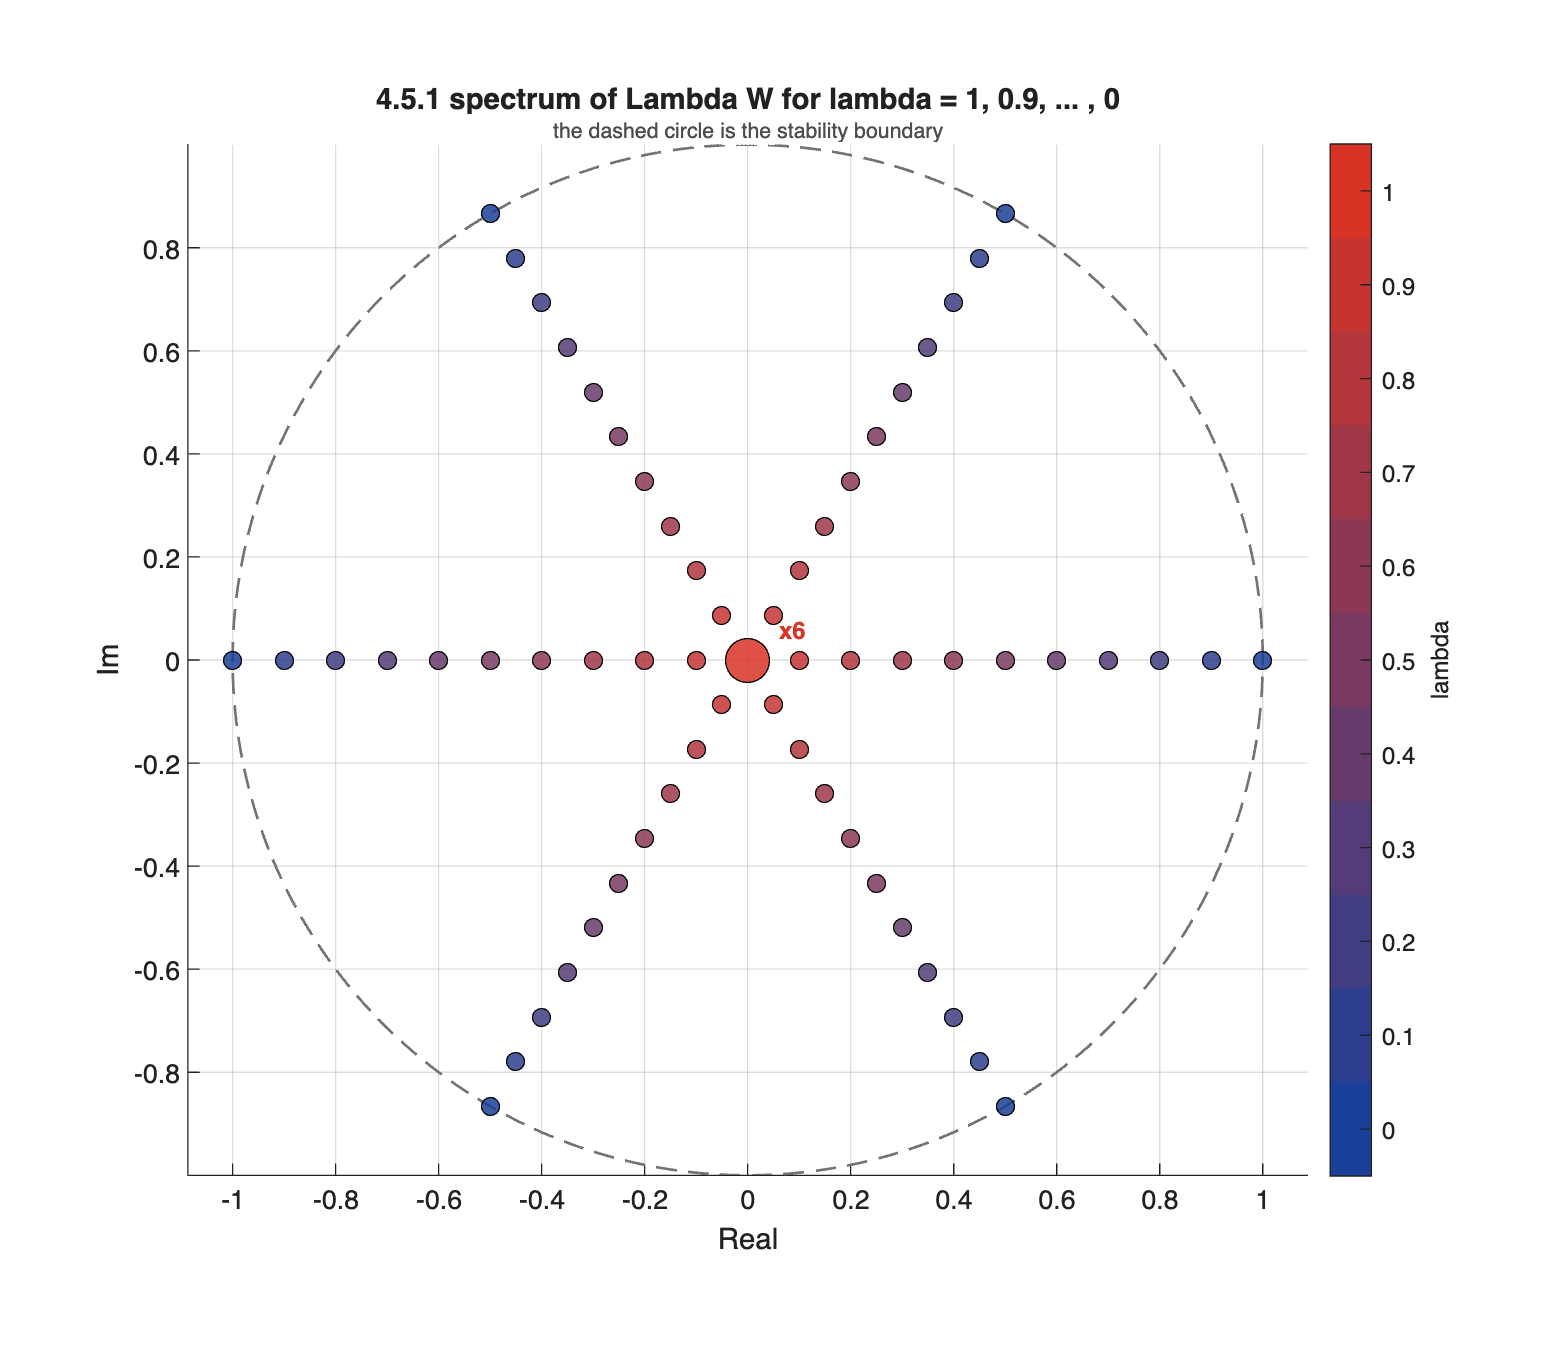

lams = 1:-0.1:0;
Ms   = arrayfun(@(l) l*W, lams, 'UniformOutput', false);

figure('Position',[0 0 800 700]);
plot_spectrum_family(Ms, lams, 'discrete', 'View','complex', 'Key','colorbar', ...
    'Label','lambda', 'Title','4.5.1 spectrum of Lambda W for lambda = 1, 0.9, ... , 0', ...
    'Subtitle','the dashed circle is the stability boundary');


fprintf('  lambda   rho(Lambda W)\n');

  lambda   rho(Lambda W)


for l = lams
    fprintf('   %.1f      %.4f\n', l, max(abs(eig(l*W))));
end

   1.0      1.0000
   0.9      0.9000
   0.8      0.8000
   0.7      0.7000
   0.6      0.6000
   0.5      0.5000
   0.4      0.4000
   0.3      0.3000
   0.2      0.2000
   0.1      0.1000
   0.0      0.0000


The spectral radius is exactly lambda, so it crosses out of the unit circle only at lambda = 1. Six representative values show what that means for the opinions themselves; each panel uses a horizon matched to its own decay rate, so every transient is visible at its own scale.

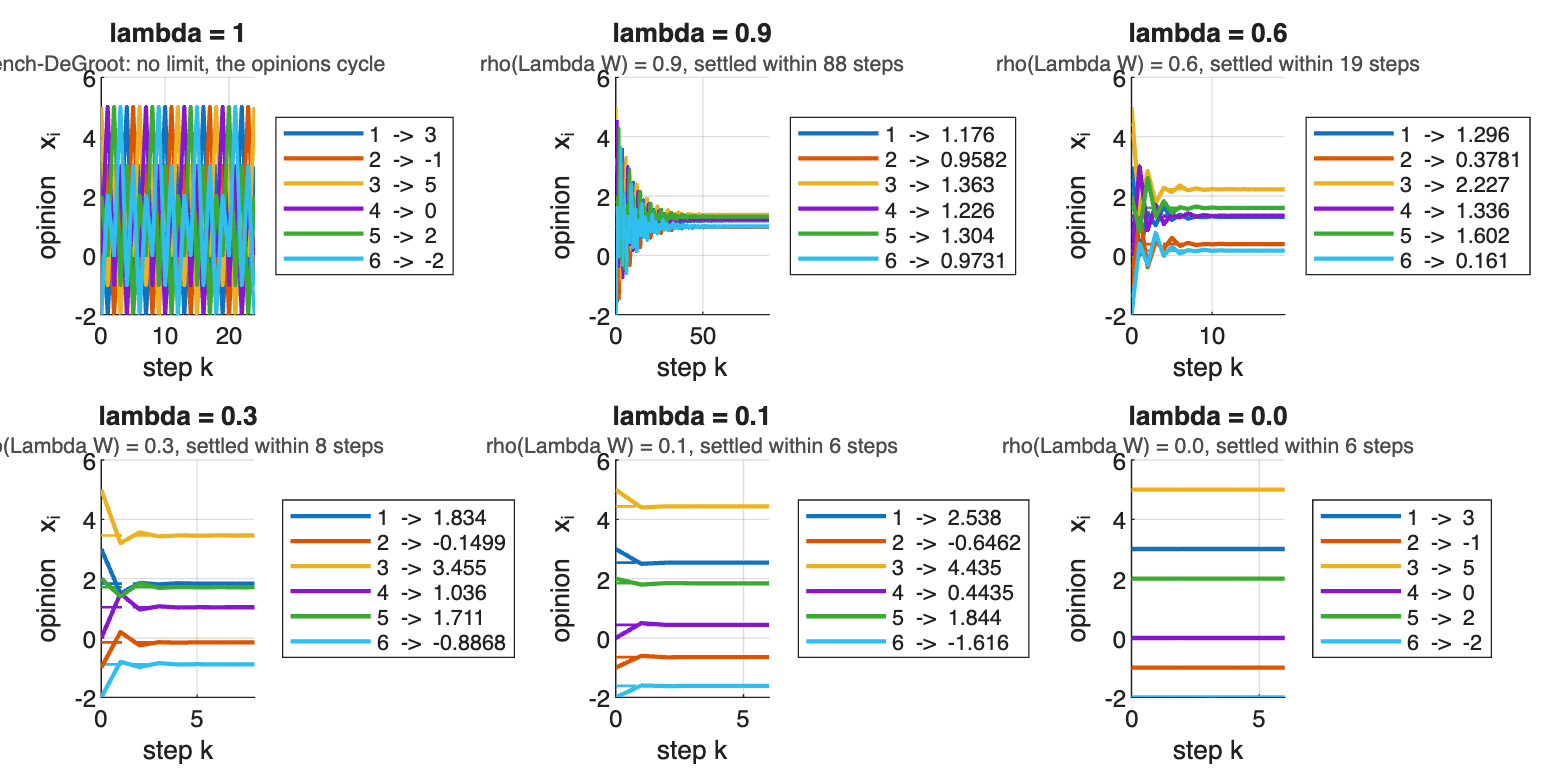

sel = [1 0.9 0.6 0.3 0.1 0];

figure('Position',[0 0 1250 620]);
tiledlayout(2, 3, 'TileSpacing','compact', 'Padding','compact');
for l = sel
    if l == 1
        Kl = 24;
        X  = sim_friedkin_johnsen(W, ones(N,1), u, x0, Kl);
        nexttile;
        plot_opinions(X, [], 'Title','lambda = 1', ...
            'Subtitle','French-DeGroot: no limit, the opinions cycle');
    else
        Kl  = min(120, max(6, ceil(log(1e-4)/log(max(l, 1e-3)))));
        lim = total_influence(W, l*ones(N,1)) * u;
        X   = sim_friedkin_johnsen(W, l*ones(N,1), u, x0, Kl);
        nexttile;
        plot_opinions(X, [], 'Limit', lim, 'Title', sprintf('lambda = %.1f', l), ...
            'Subtitle', sprintf('rho(Lambda W) = %.1f, settled within %d steps', l, Kl));
    end
end

The two figures are the same statement twice. Plotting the distance to the limit against the step confirms it: each trajectory decays as lambda to the power k, so the radius read off the spectrum is the slope seen in the dynamics.

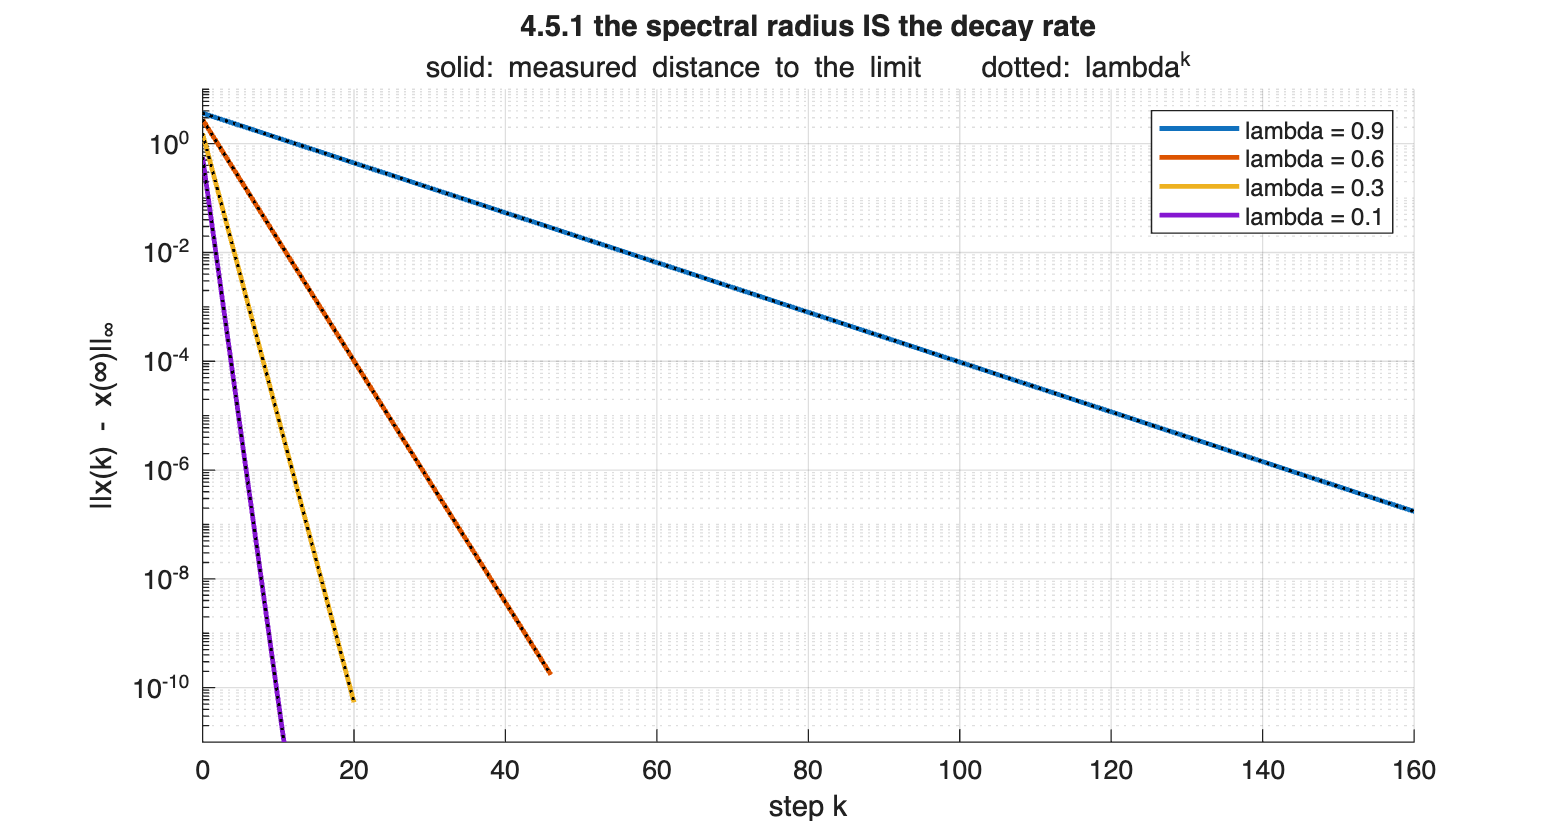

figure('Position',[0 0 900 480]); hold on
co = lines(4);  j = 0;
for l = [0.9 0.6 0.3 0.1]
    j  = j + 1;
    Kl = ceil(log(1e-10)/log(l));
    xi = total_influence(W, l*ones(N,1)) * u;
    X  = sim_friedkin_johnsen(W, l*ones(N,1), u, x0, Kl);
    plot(0:Kl, max(max(abs(X - xi), [], 1), 1e-12), 'LineWidth', 1.8, 'Color', co(j,:), ...
        'DisplayName', sprintf('lambda = %.1f', l));
    plot(0:Kl, max(abs(X(:,1)-xi))*l.^(0:Kl), ':', 'Color', 'k', ...
        'LineWidth', 1.1, 'HandleVisibility', 'off');
end
set(gca, 'YScale', 'log'); grid on; legend('Location','northeast');
xlim([0 160]); ylim([1e-11 10]);
xlabel('step k'); ylabel('||x(k) - x(\infty)||_\infty');
title('4.5.1 the spectral radius IS the decay rate', 'FontWeight','bold');
subtitle('solid: measured distance to the limit    dotted: lambda^k');

One caveat, since the cycle is a special topology. For any row-stochastic W the spectral radius of Lambda W is lambda, because rho(W) = 1; so the slowest mode always decays at lambda. What is special about the cycle is that ALL six of its eigenvalues have modulus lambda, so the whole transient decays at that one rate. On a denser graph the remaining eigenvalues are much smaller and the transient dies far sooner than lambda to the k suggests.

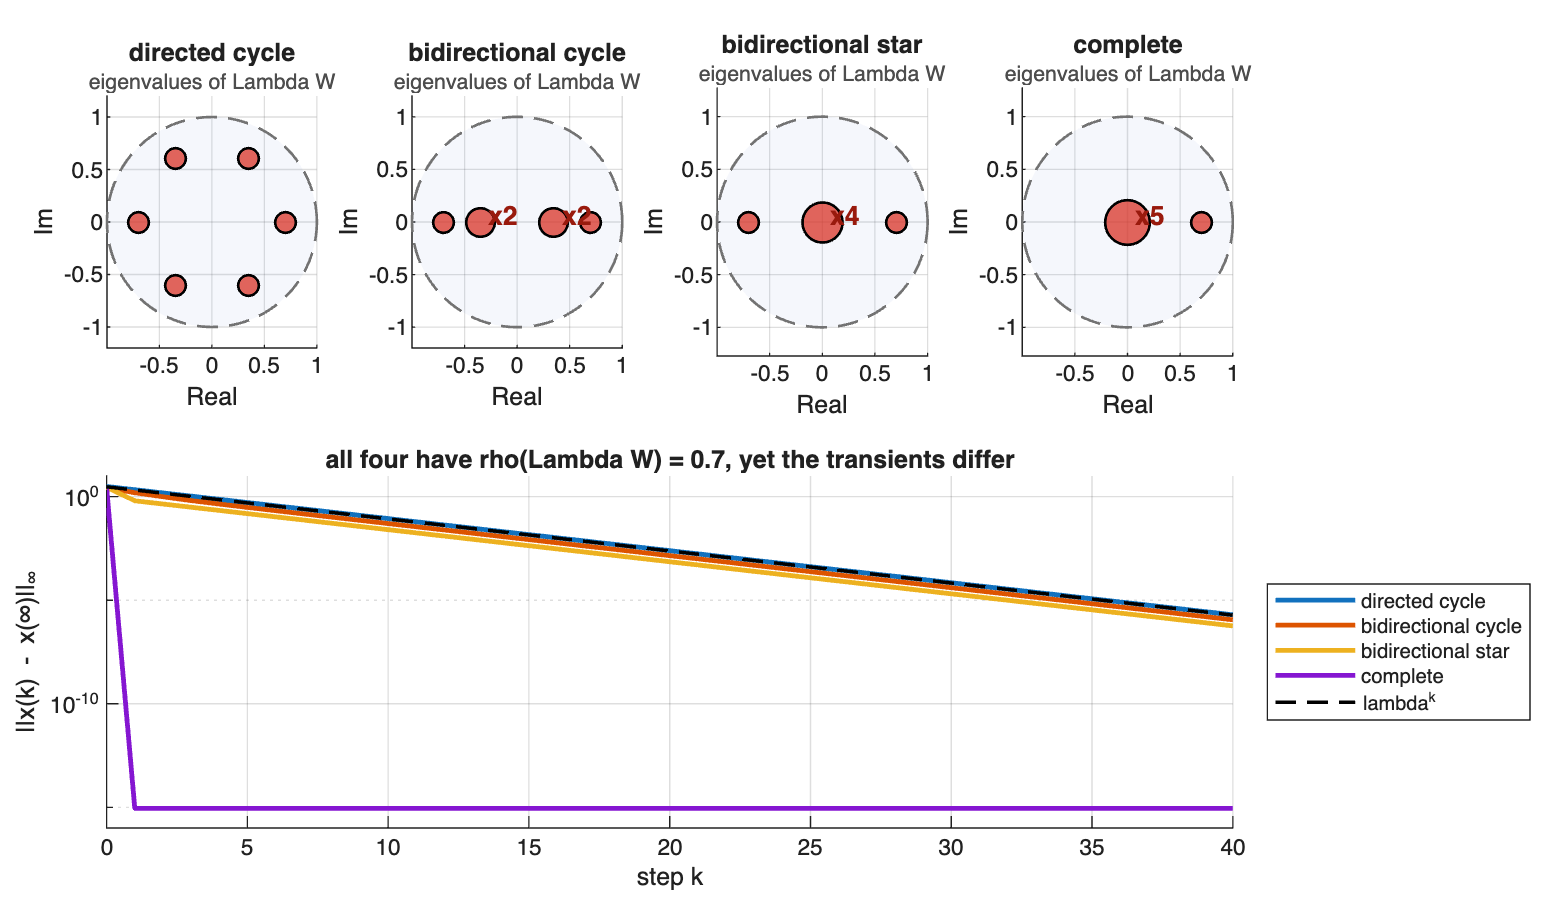

tops = {'directed cycle',      row_stochastic(ring_graph(N)); ...
        'bidirectional cycle', row_stochastic(ring_graph(N) + ring_graph(N).'); ...
        'bidirectional star',  row_stochastic(star_graph(N,'bidirectional')); ...
        'complete',            row_stochastic(complete_graph(N))};
lamc = 0.7;

figure('Position',[0 0 1250 720]);
tiledlayout(2, 4, 'TileSpacing','compact', 'Padding','compact');
for k = 1:4
    nexttile;
    plot_eigenvalues(lamc*tops{k,2}, 'discrete', 'Title', tops{k,1}, ...
        'Subtitle','eigenvalues of Lambda W');
end

nexttile([1 4]); hold on
Kc = 40;  co = lines(4);
for k = 1:4
    Wk = tops{k,2};
    xi = total_influence(Wk, lamc*ones(N,1)) * u;
    X  = sim_friedkin_johnsen(Wk, lamc*ones(N,1), u, x0, Kc);
    plot(0:Kc, max(max(abs(X - xi), [], 1), 1e-16), 'LineWidth', 1.8, ...
        'Color', co(k,:), 'DisplayName', tops{k,1});
end
plot(0:Kc, 3*lamc.^(0:Kc), 'k--', 'LineWidth', 1.3, 'DisplayName','lambda^k');
set(gca, 'YScale','log'); grid on; legend('Location','eastoutside');
xlim([0 Kc]); ylim([1e-16 10]);
xlabel('step k'); ylabel('||x(k) - x(\infty)||_\infty');
title('all four have rho(Lambda W) = 0.7, yet the transients differ', 'FontWeight','bold');

The outermost eigenvalue is at 0.7 in all four cases, but the interiors are not alike: the cycle keeps all six on that circle, the complete graph puts five of them at the origin, and it reaches its limit in a single step. The susceptibility fixes the slowest rate; the topology fixes everything else.

## 4.5.2 The decomposition, and what decides convergence

Section 4.2 splits the agents into P-dependent ones, which some prejudice reaches, and P-independent ones, which none does, and writes the model as (M4.1.1) and (M4.1.2). The second block is driven by W22 alone and is therefore an ordinary French-DeGroot model. Below, only agent 1 is prejudiced and agents 4, 5, 6 form a group that listens only to itself.

Wb = zeros(N);
Wb(1,2) = 1;                                 % 1 is prejudiced and listens to 2
Wb(2,1) = 0.5;  Wb(2,4) = 0.5;               % 2 listens to 1 and to the closed group
Wb(3,2) = 1;                                 % 3 listens to 2
Wb(4,6) = 1;  Wb(5,4) = 1;  Wb(6,5) = 1;     % a directed 3-cycle, closed on itself

lambda = [0.5; 1; 1; 1; 1; 1];               % only agent 1 is prejudiced

pd = prejudice_reach(Wb, lambda < 1);
p1 = find(pd).';   p2 = find(~pd).';
fprintf('prejudiced (lambda < 1) : %s\n', mat2str(find(lambda < 1).'));

prejudiced (lambda < 1) : 1


fprintf('P-dependent   (PD)      : %s\n', mat2str(p1));

P-dependent   (PD)      : [1 2 3]


fprintf('P-independent (PI)      : %s\n', mat2str(p2));

P-independent (PI)      : [4 5 6]


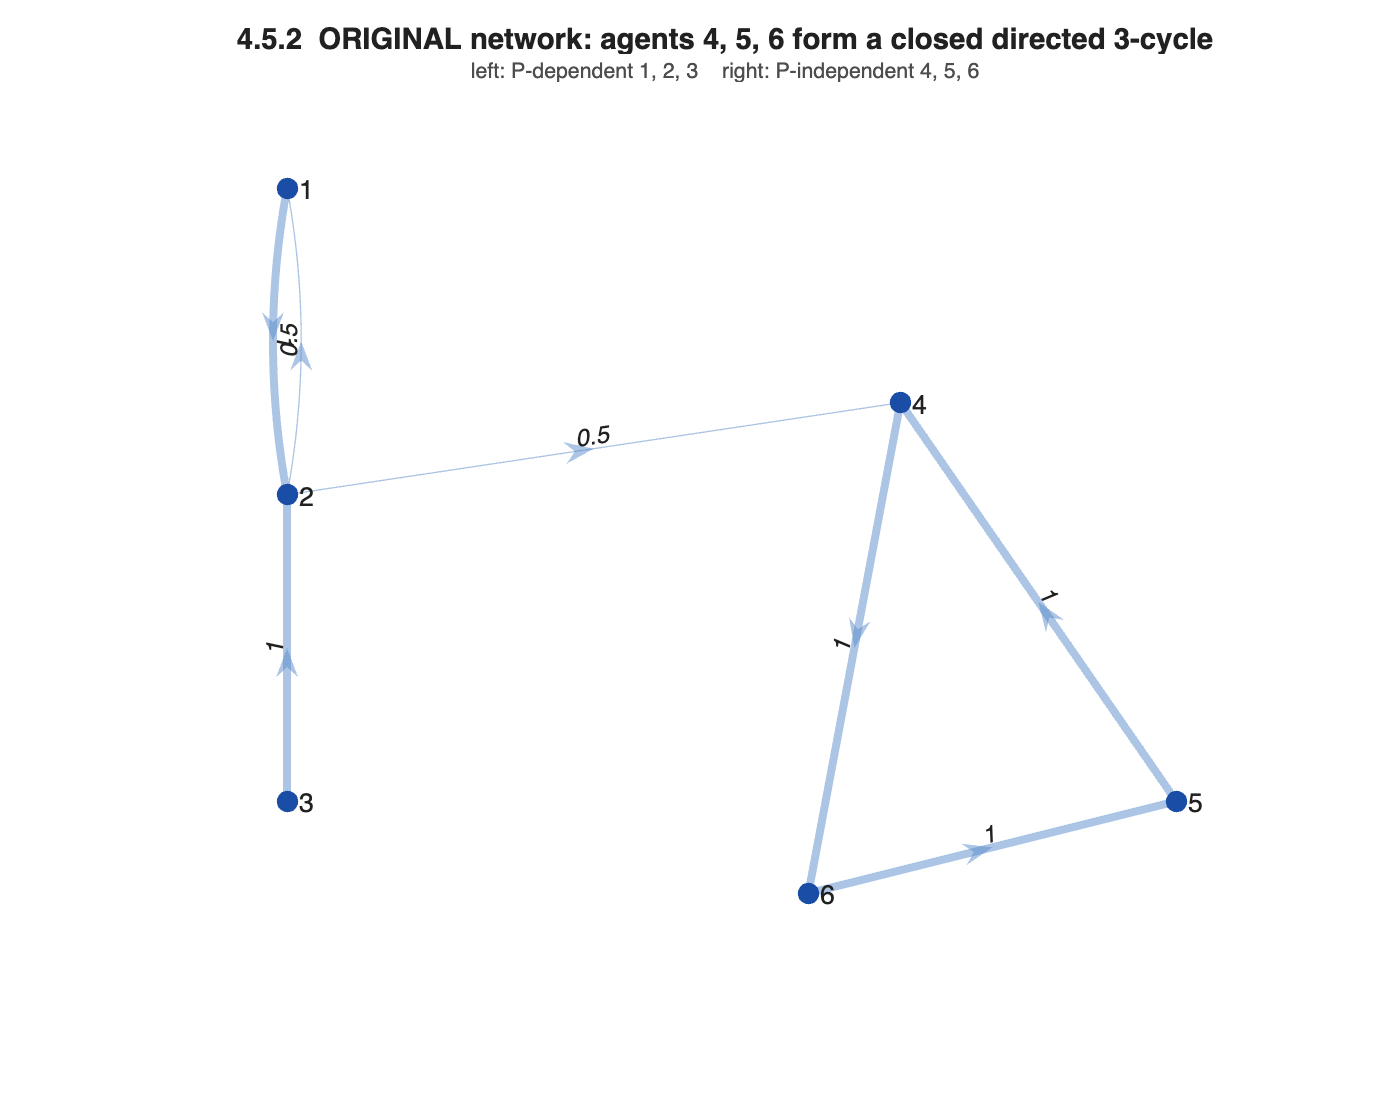


pos = zeros(N,2);
pos(p1,:) = [zeros(3,1), (3:-1:1).'];
pos(p2,:) = [2.0 2.3; 2.9 1.0; 1.7 0.7];

figure('Position',[0 0 700 560]);
plot_graph(Wb, [], 'Layout', pos, ...
    'Title','4.5.2  ORIGINAL network: agents 4, 5, 6 form a closed directed 3-cycle', ...
    'Subtitle','left: P-dependent 1, 2, 3    right: P-independent 4, 5, 6')

L11 = diag(lambda(p1));
W11 = Wb(p1,p1);
W22 = Wb(p2,p2)

W22 =      0     0     1
     1     0     0
     0     1     0



fprintf('rho(Lambda11 W11) = %.4f   -> Schur stable = %d   (Theorem 4.1)\n', ...
    max(abs(eig(L11*W11))), max(abs(eig(L11*W11))) < 1);

rho(Lambda11 W11) = 0.5000   -> Schur stable = 1   (Theorem 4.1)


fprintf('W22 stochastic = %d,  period %d,  regular = %d\n', ...
    is_row_stochastic(W22), graph_period(W22), graph_summary(W22).convergent);

W22 stochastic = 1,  period 3,  regular = 0


Theorem 4.1 guarantees the first block whatever the rest of the network does. It does not guarantee the second, and here W22 is a directed 3-cycle, hence periodic and not regular.

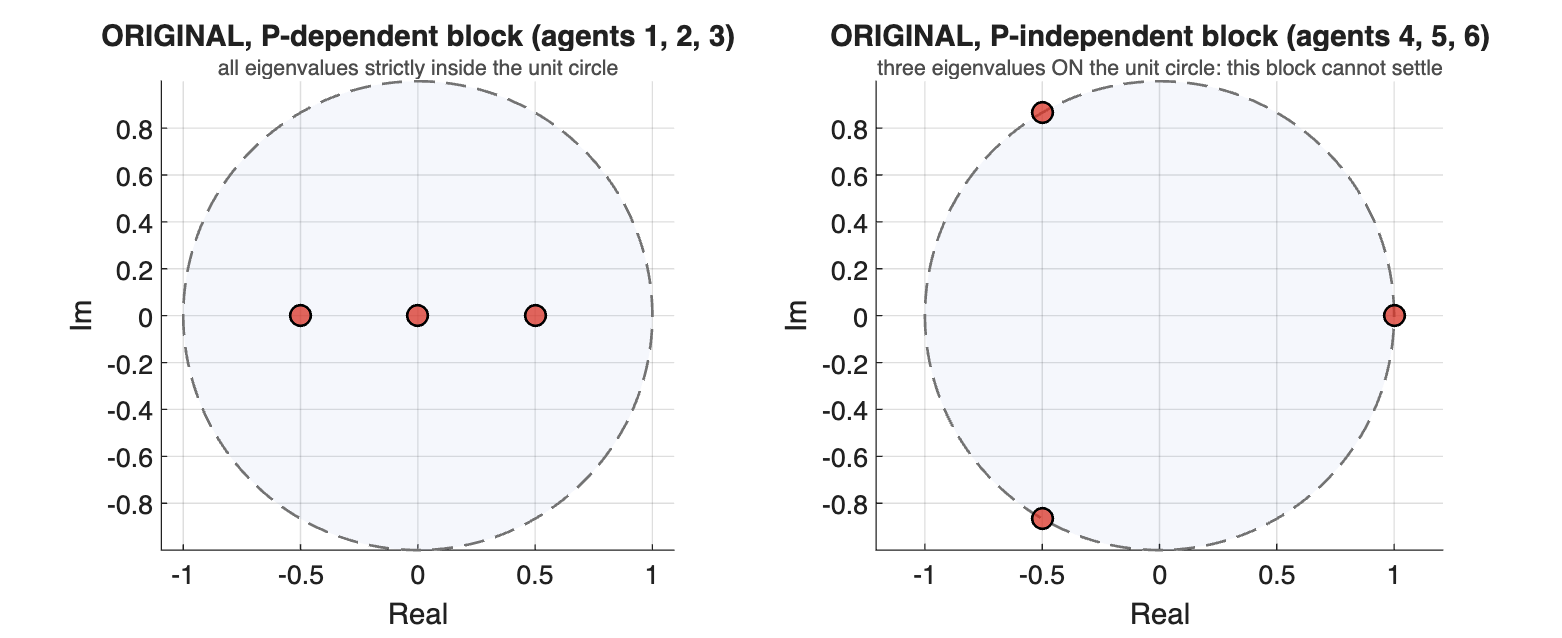

figure('Position',[0 0 1150 470]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_eigenvalues(L11*W11, 'discrete', ...
    'Title','ORIGINAL, P-dependent block (agents 1, 2, 3)', ...
    'Subtitle','all eigenvalues strictly inside the unit circle');
nexttile;
plot_eigenvalues(W22, 'discrete', ...
    'Title','ORIGINAL, P-independent block (agents 4, 5, 6)', ...
    'Subtitle','three eigenvalues ON the unit circle: this block cannot settle');

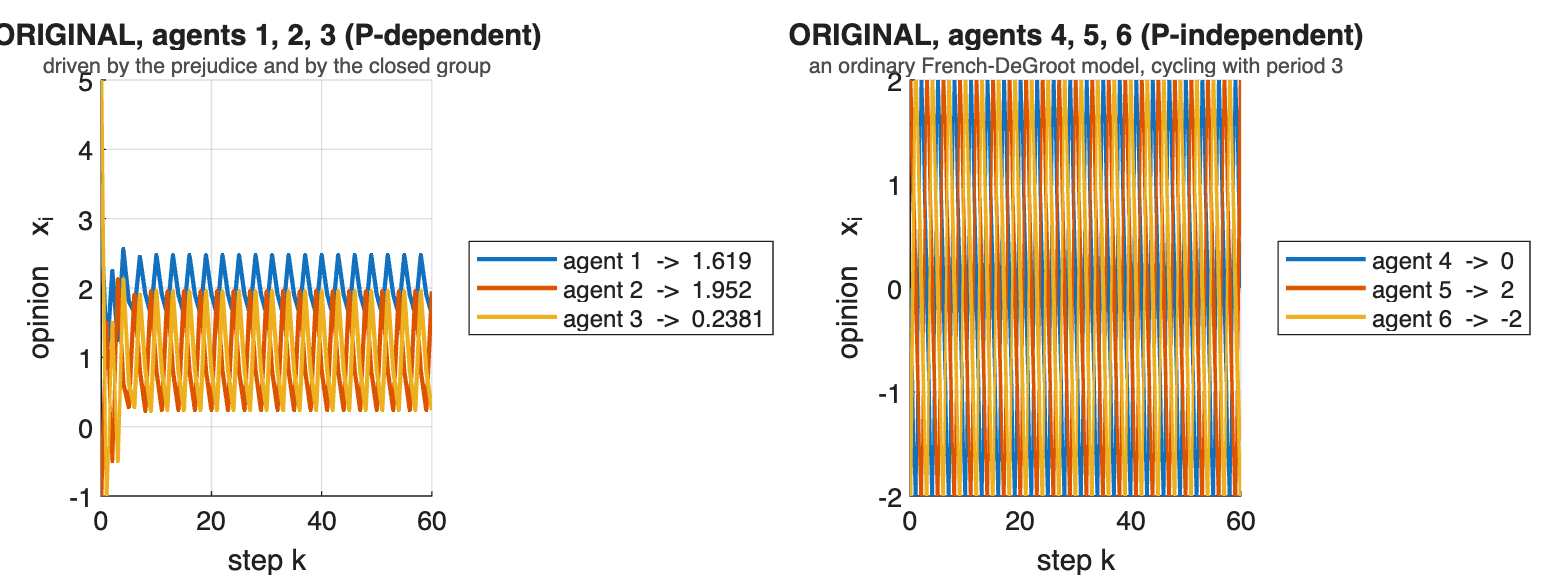

X = sim_friedkin_johnsen(Wb, lambda, u, x0, 60);

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_opinions(X(p1,:), [], 'Labels', compose('agent %d', p1), ...
    'Title','ORIGINAL, agents 1, 2, 3 (P-dependent)', ...
    'Subtitle','driven by the prejudice and by the closed group');
nexttile;
plot_opinions(X(p2,:), [], 'Labels', compose('agent %d', p2), ...
    'Title','ORIGINAL, agents 4, 5, 6 (P-independent)', ...
    'Subtitle','an ordinary French-DeGroot model, cycling with period 3');


fprintf('ORIGINAL network settled by step 60 ?  %d\n', ...
    max(abs(X(:,end) - X(:,end-1))) < 1e-8);

ORIGINAL network settled by step 60 ?  0


Corollary 4.2 says the model converges exactly when W22 is regular, so breaking the period of the closed group is enough to repair it. The modification is a single edge: agent 4 now also listens to itself. Everything else, including the P-dependent block, is unchanged.

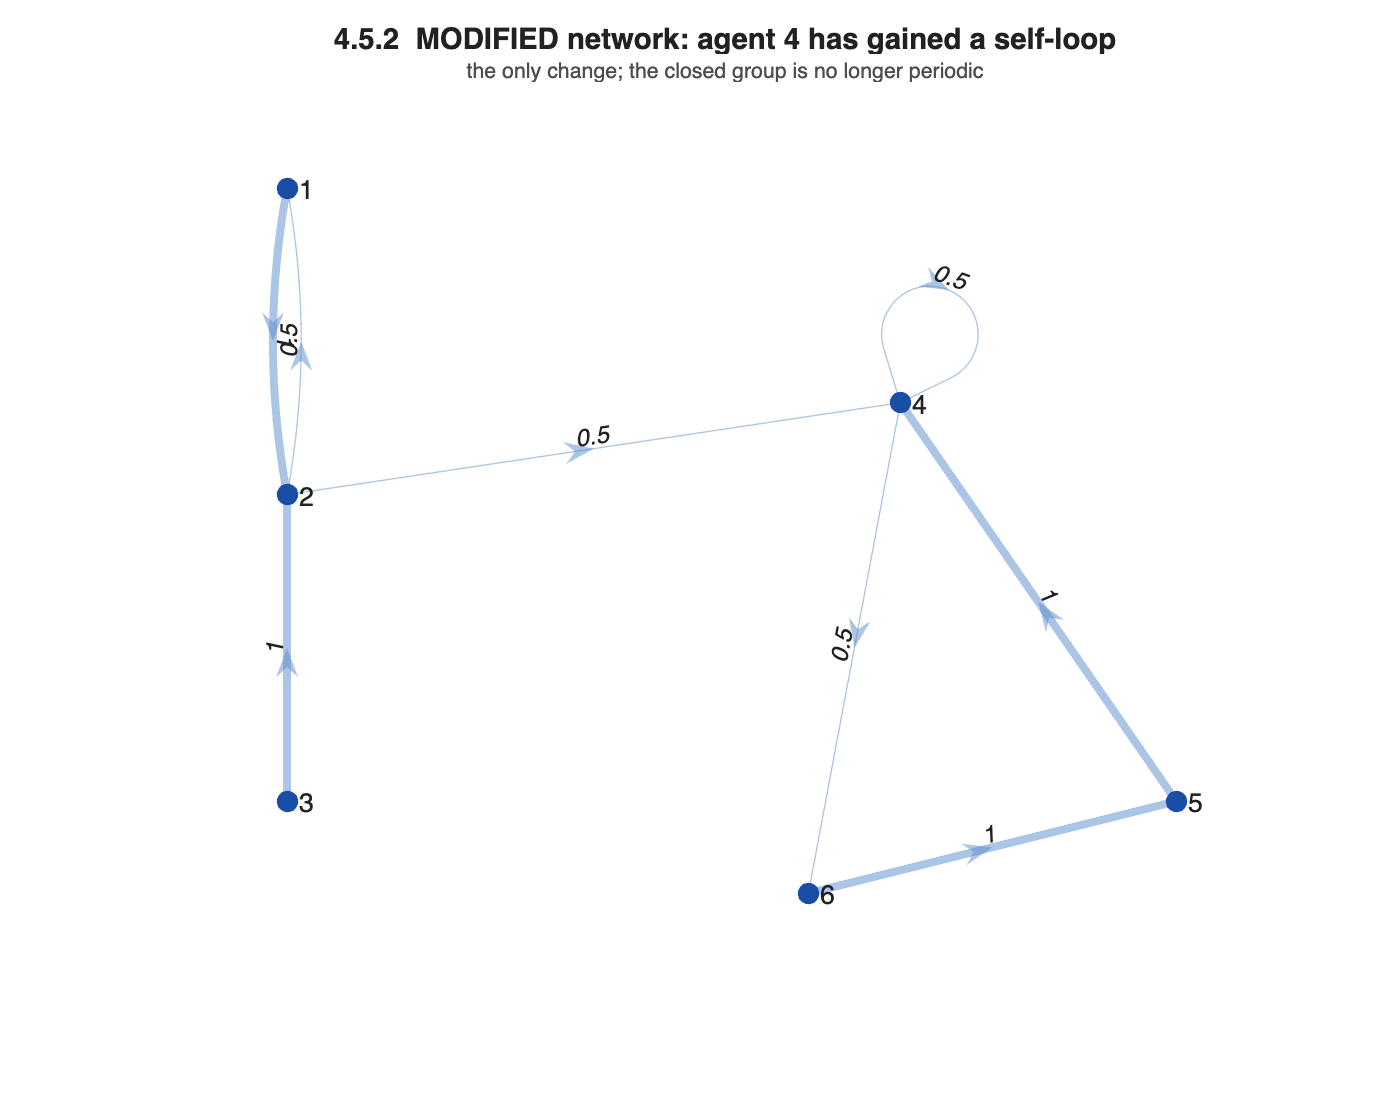

Wc = Wb;
Wc(4,4) = 0.5;  Wc(4,6) = 0.5;      % agent 4 now splits its attention with itself

figure('Position',[0 0 700 560]);
plot_graph(Wc, [], 'Layout', pos, ...
    'Title','4.5.2  MODIFIED network: agent 4 has gained a self-loop', ...
    'Subtitle','the only change; the closed group is no longer periodic')


W22c = Wc(p2,p2)

W22c =     0.5000         0    0.5000
    1.0000         0         0
         0    1.0000         0



fprintf('W22 period  : %d  (original)  ->  %d  (modified)\n', ...
    graph_period(W22), graph_period(W22c));

W22 period  : 3  (original)  ->  1  (modified)


fprintf('W22 regular : %d  (original)  ->  %d  (modified)\n', ...
    graph_summary(W22).convergent, graph_summary(W22c).convergent);

W22 regular : 0  (original)  ->  1  (modified)


fprintf('rho(Lambda11 W11) unchanged at %.4f\n', ...
    max(abs(eig(diag(lambda(p1))*Wc(p1,p1)))));

rho(Lambda11 W11) unchanged at 0.5000


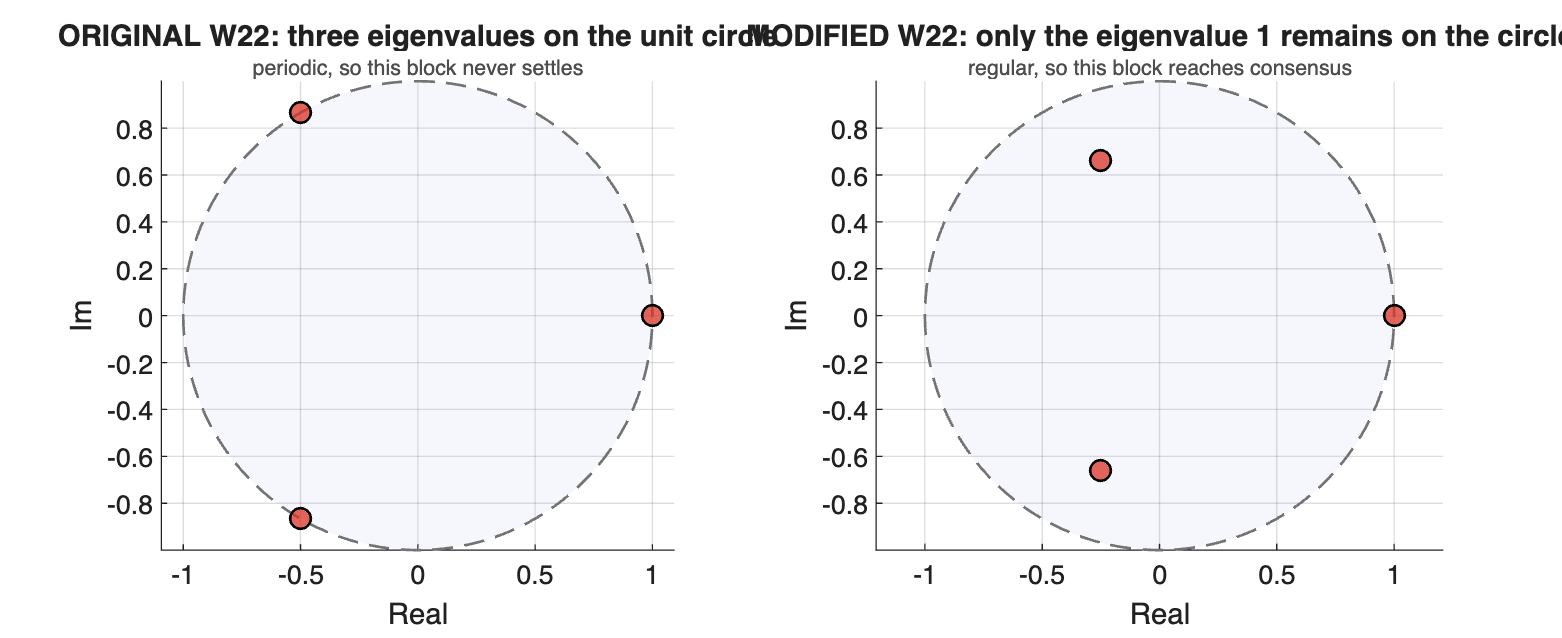

figure('Position',[0 0 1150 470]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_eigenvalues(W22, 'discrete', ...
    'Title','ORIGINAL W22: three eigenvalues on the unit circle', ...
    'Subtitle','periodic, so this block never settles');
nexttile;
plot_eigenvalues(W22c, 'discrete', ...
    'Title','MODIFIED W22: only the eigenvalue 1 remains on the circle', ...
    'Subtitle','regular, so this block reaches consensus');

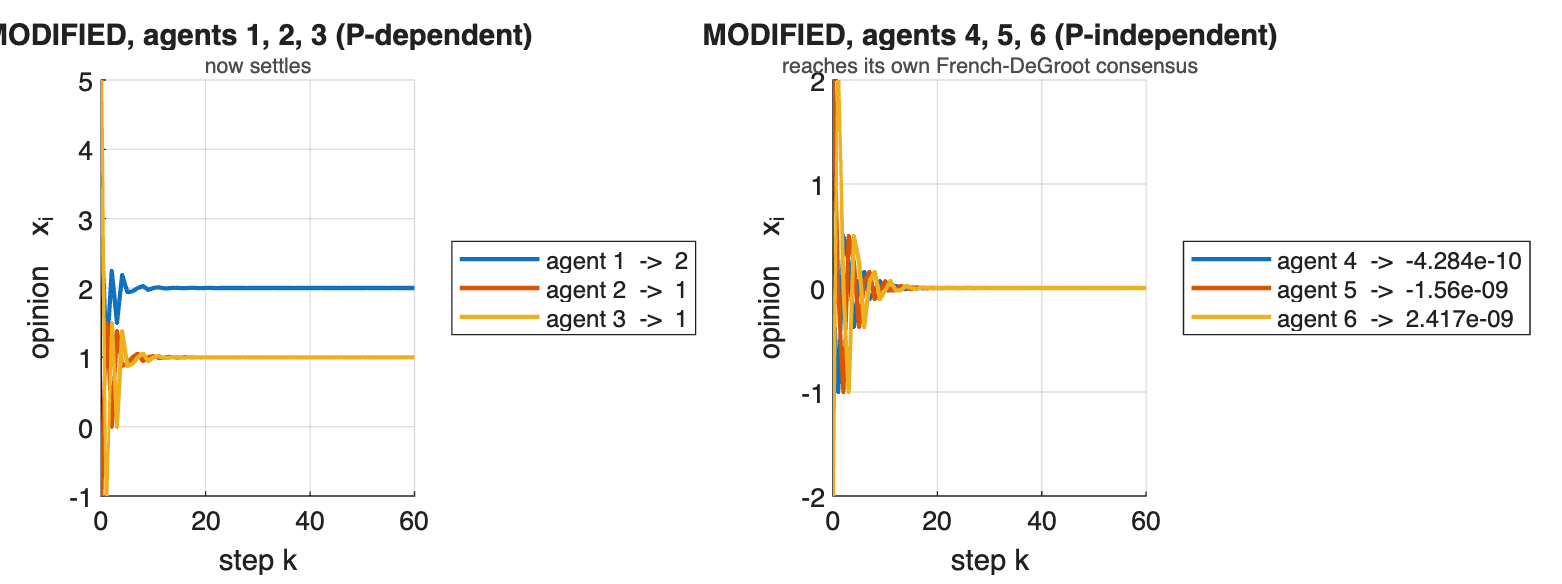

Xc = sim_friedkin_johnsen(Wc, lambda, u, x0, 60);

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_opinions(Xc(p1,:), [], 'Labels', compose('agent %d', p1), ...
    'Title','MODIFIED, agents 1, 2, 3 (P-dependent)', 'Subtitle','now settles');
nexttile;
plot_opinions(Xc(p2,:), [], 'Labels', compose('agent %d', p2), ...
    'Title','MODIFIED, agents 4, 5, 6 (P-independent)', ...
    'Subtitle','reaches its own French-DeGroot consensus');


fprintf('MODIFIED network settled by step 60 ?  %d\n', ...
    max(abs(Xc(:,end) - Xc(:,end-1))) < 1e-8);

MODIFIED network settled by step 60 ?  1


One self-loop moved two eigenvalues off the unit circle, and with them the whole model went from cycling forever to settling. This is where the discrete-time model departs from its continuous-time counterpart: there the P-independent block was an Abelson model, which converges for any weights, so the whole system always converged. Here it is a French-DeGroot model, which can be periodic, so asymptotic stability of the P-dependent block is not enough and Corollary 4.2 has real content.

## 4.5.3 Influence centrality and PageRank

Section 4.3 asks how social power extends to this model. With u = x(0) the limit is x(inf) = V x(0), and since the agents do not agree there is no single final opinion to weigh against; (E4.2) averages agent is weight across all the final opinions instead. Before computing any centrality, the system itself: this is a dynamical model, and the centrality is read off its limit.

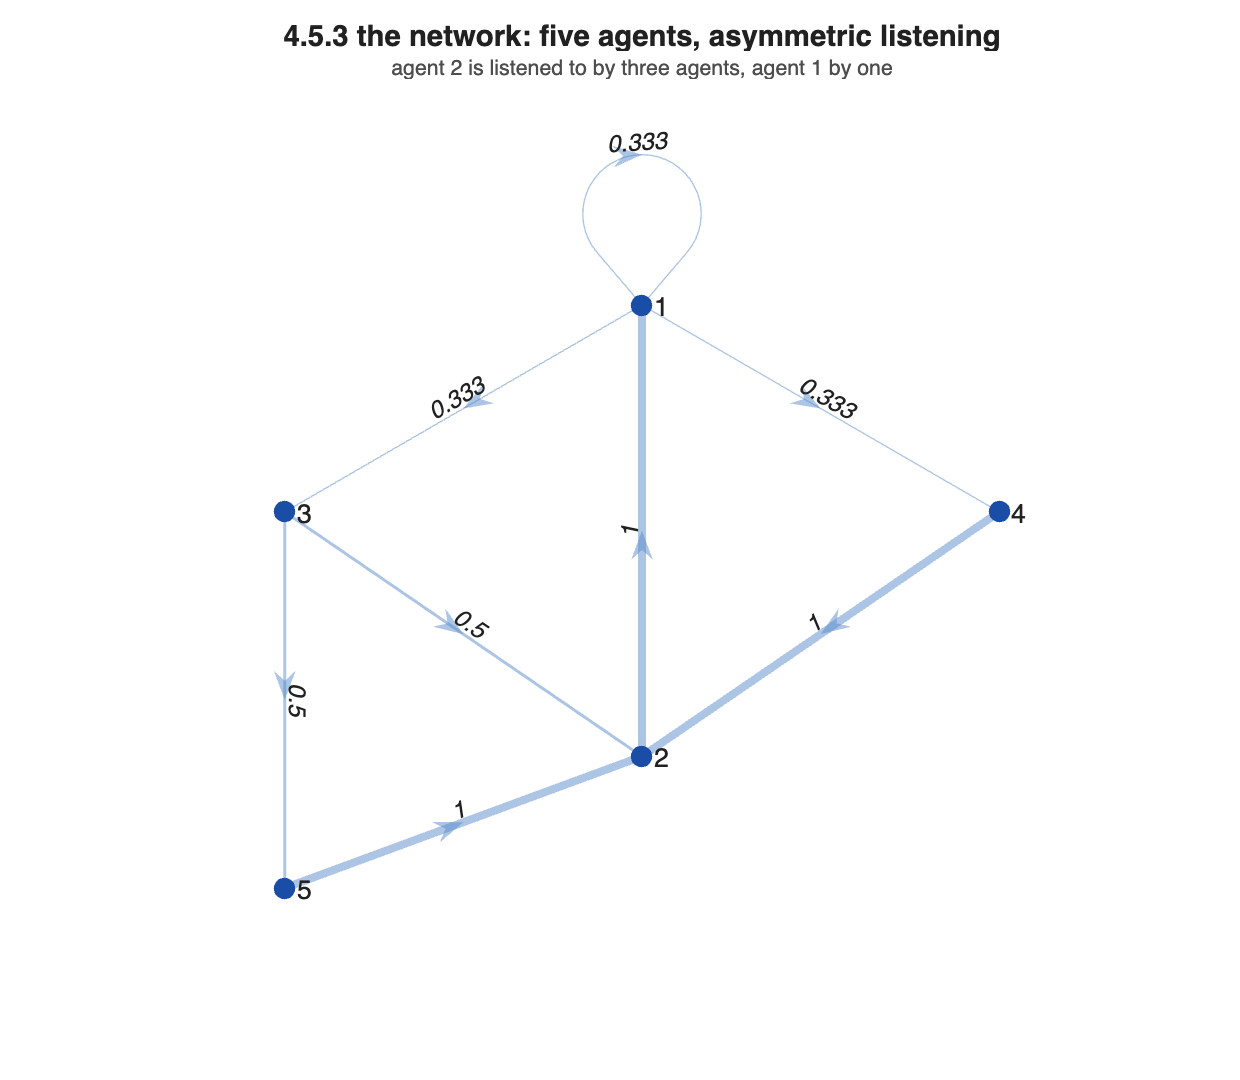

A = [1 0 1 1 0        % 1 listens to itself, to 3 and to 4
     1 0 0 0 0        % 2 listens only to 1
     0 1 0 0 1        % 3 listens to 2 and to 5
     0 1 0 0 0        % 4 listens only to 2
     0 1 0 0 0];      % 5 listens only to 2
Wc5 = row_stochastic(A);
n   = 5;
xc  = [8; 2; 5; 1; 9];      % initial opinions, and also the prejudices
uc  = xc;

posc = [0 1.2; 0 -1.2; -1.9 0.1; 1.9 0.1; -1.9 -1.9];
figure('Position',[0 0 620 540]);
plot_graph(Wc5, [], 'Layout', posc, ...
    'Title','4.5.3 the network: five agents, asymmetric listening', ...
    'Subtitle','agent 2 is listened to by three agents, agent 1 by one')

The model is asymptotically stable here for any lambda below 1, since W is strongly connected (Corollary 4.1). At lambda = 0.85 the spectrum sits well inside the unit circle and the opinions settle, but not on a common value: this is convergence to persistent disagreement, and V having full rank is what that means.

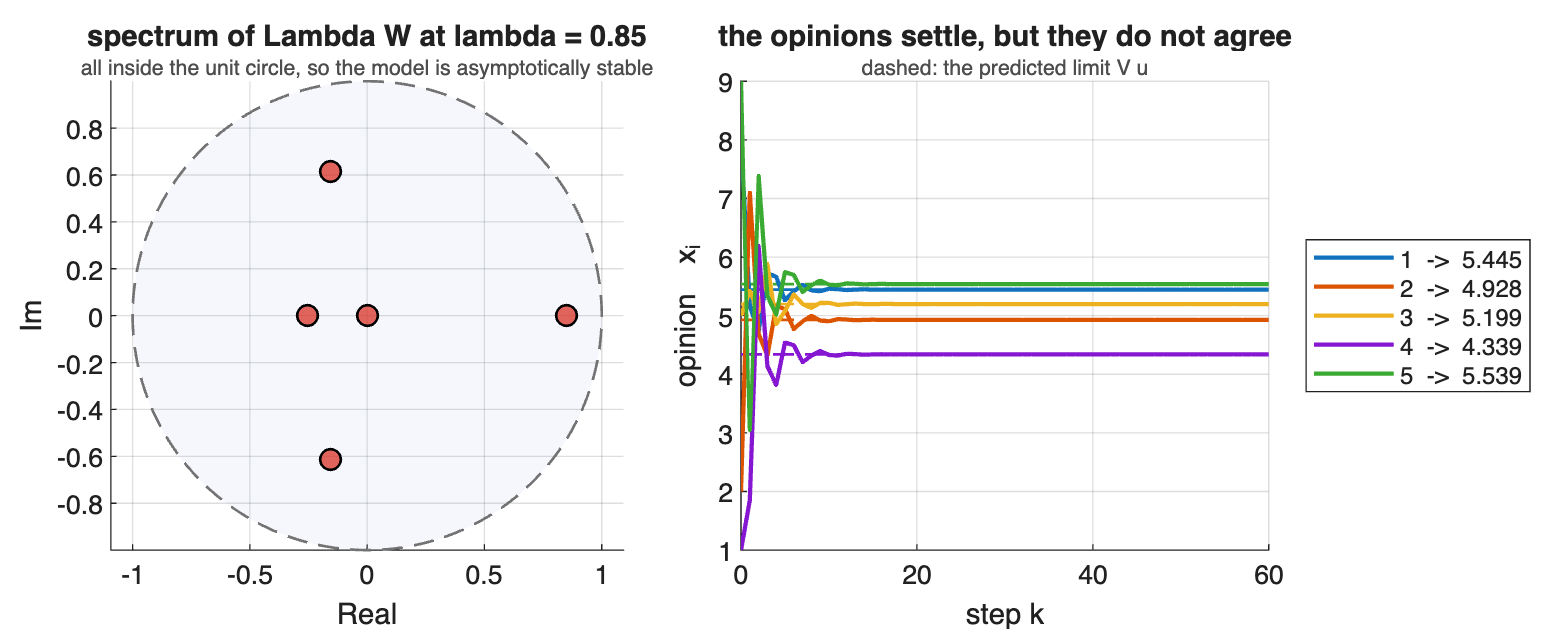

lam = 0.85;
V   = total_influence(Wc5, lam*ones(n,1));
xi  = V * uc;
Xc5 = sim_friedkin_johnsen(Wc5, lam*ones(n,1), uc, xc, 60);

figure('Position',[0 0 1150 470]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_eigenvalues(lam*Wc5, 'discrete', ...
    'Title','spectrum of Lambda W at lambda = 0.85', ...
    'Subtitle','all inside the unit circle, so the model is asymptotically stable');
nexttile;
plot_opinions(Xc5, [], 'Limit', xi, ...
    'Title','the opinions settle, but they do not agree', ...
    'Subtitle','dashed: the predicted limit V u');


fprintf('rho(Lambda W)          : %.4f\n', max(abs(eig(lam*Wc5))));

rho(Lambda W)          : 0.8500


fprintf('rank(V)                : %d of %d\n', rank(V), n);

rank(V)                : 5 of 5


fprintf('spread of the limit    : %.4f\n', max(xi) - min(xi));

spread of the limit    : 1.2000


fprintf('|x(60) - V u|          : %.2e\n', max(abs(Xc5(:,end) - xi)));

|x(60) - V u|          : 3.38e-12


Each agent therefore ends somewhere different, and V records exactly how much of each prejudice went into each final opinion. Averaging the columns of V gives (E4.2), the mean weight of agent i across the whole group.

p = social_power(Wc5);            % French social power, for comparison
c = influence_centrality(Wc5, lam)

c =     0.3686
    0.2755
    0.1344
    0.1344
    0.0871


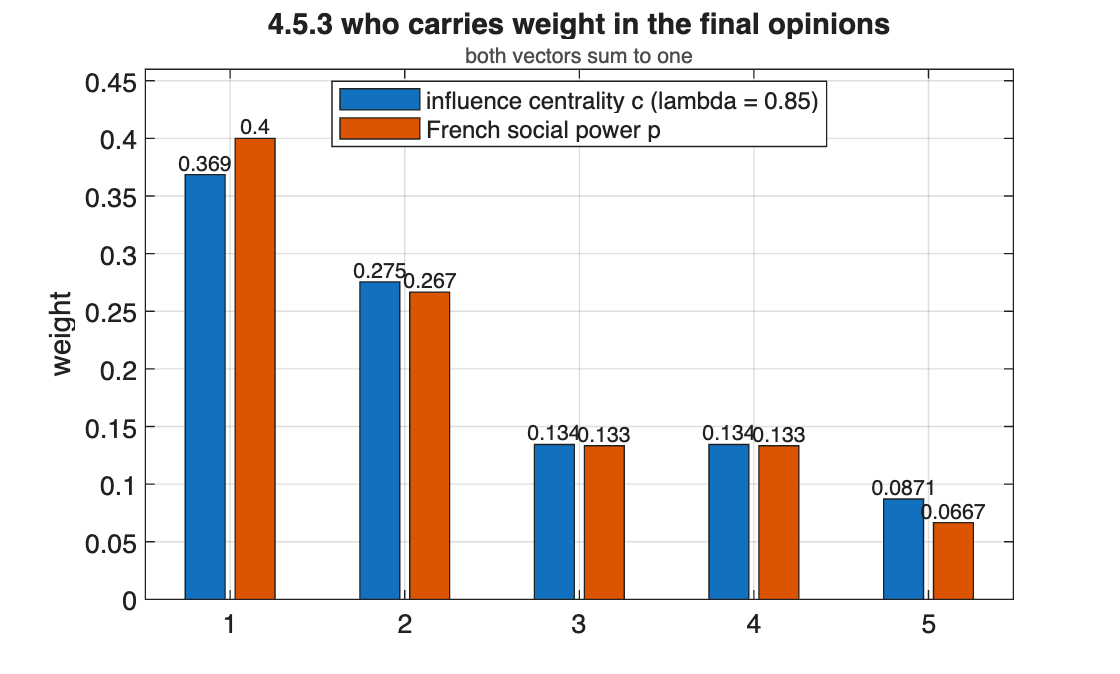


figure;
plot_bars([c, p], [], 'Series', {'influence centrality c (lambda = 0.85)', ...
    'French social power p'}, 'YLabel','weight', ...
    'Title','4.5.3 who carries weight in the final opinions', ...
    'Subtitle','both vectors sum to one')

They rank the agents almost the same way here, but they are not the same quantity. Lemma 4.1 says the second is the limit of the first: as lambda goes to one, c(lambda) tends to p. At the other end lambda = 0 gives V = I and influence spread equally.

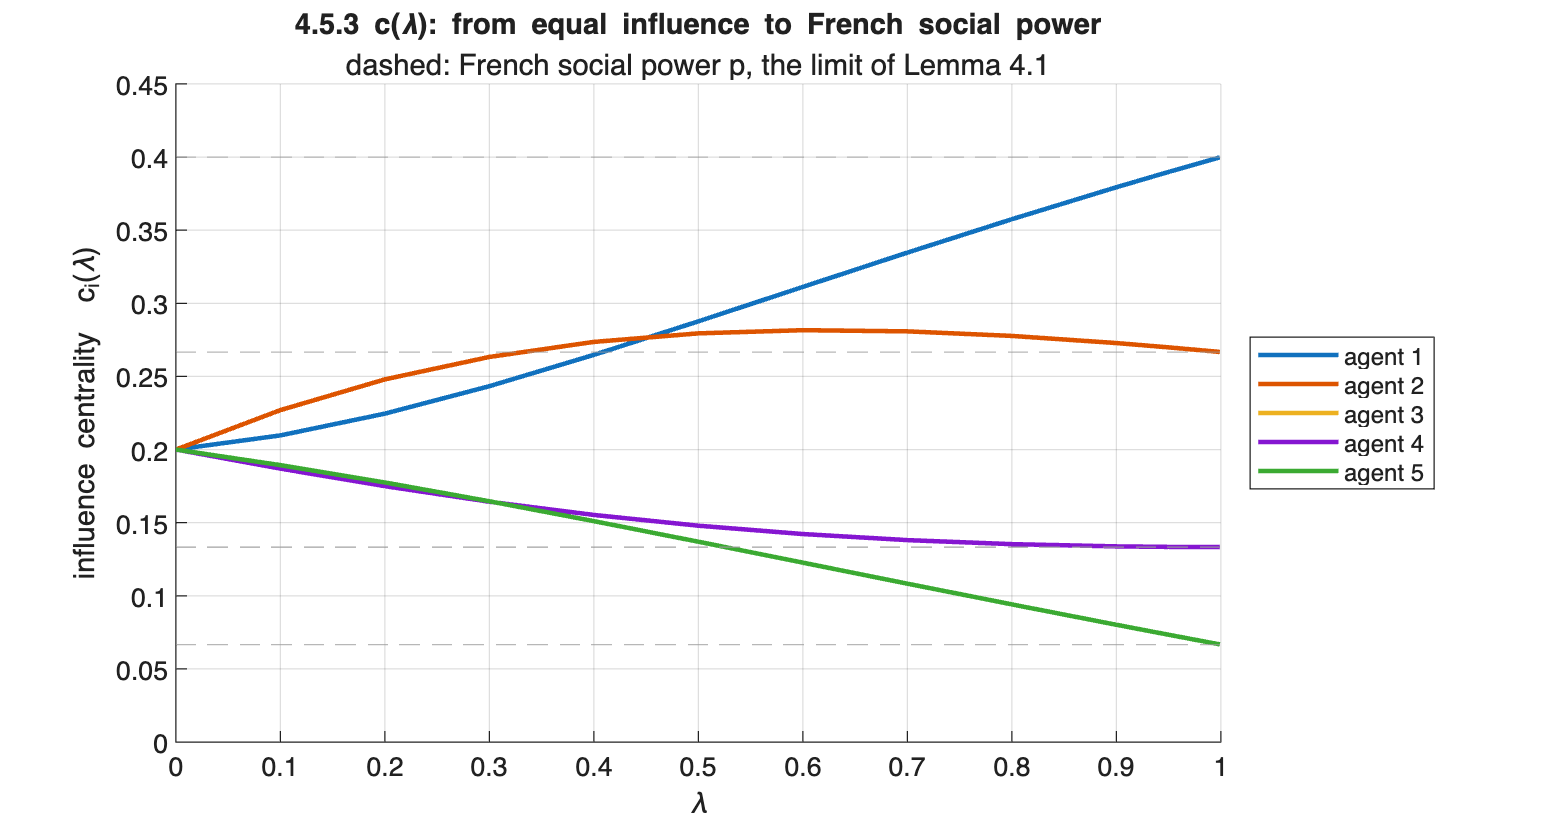

lams = [0 0.1:0.1:0.9 0.95 0.99 0.999];
Cs   = zeros(n, numel(lams));
for j = 1:numel(lams), Cs(:,j) = influence_centrality(Wc5, lams(j)); end

figure('Position',[0 0 880 470]); hold on
h = plot(lams, Cs.', 'LineWidth', 1.7);
for i = 1:n, yline(p(i), '--', 'Color', [.6 .6 .6]); end
legend(h, compose('agent %d', 1:n), 'Location','eastoutside');
grid on; xlabel('\lambda'); ylabel('influence centrality  c_i(\lambda)');
xlim([0 1]); ylim([0 0.45]);
title('4.5.3 c(\lambda): from equal influence to French social power', 'FontWeight','bold');
subtitle('dashed: French social power p, the limit of Lemma 4.1');


fprintf('c(0) is exactly uniform: max|c(0) - 1/n| = %.2e\n\n', max(abs(Cs(:,1) - 1/n)));

c(0) is exactly uniform: max|c(0) - 1/n| = 0.00e+00



fprintf('  lambda    spread of c    ||c - p||    ranking\n');

  lambda    spread of c    ||c - p||    ranking


for j = [2 3 4 7 10 12 13]
    [~, ord] = sort(Cs(:,j), 'descend');
    fprintf('  %-8g  %.4f         %.4f       %s\n', lams(j), ...
        max(Cs(:,j)) - min(Cs(:,j)), max(abs(Cs(:,j)-p)), mat2str(ord.'));
end

  0.1       0.0400         0.1903       [2 1 5 3 4]
  0.2       0.0730         0.1754       [2 1 5 3 4]
  0.3       0.0990         0.1567       [2 1 5 3 4]
  0.6       0.1885         0.0888       [1 2 3 4 5]
  0.9       0.2991         0.0207       [1 2 4 3 5]
  0.99      0.3300         0.0020       [1 2 3 4 5]
  0.999     0.3330         0.0002       [1 2 3 4 5]


The ranking itself depends on lambda, and the curves cross near 0.46. At low susceptibility the agents barely pass opinions on, so influence is close to being counted by direct listeners and agent 2, listened to by three agents, leads. As lambda grows, influence travels along chains and agent 1 takes over, because it is listened to by agent 2. Susceptibility controls how far influence is allowed to propagate before it is discounted.

That is exactly the role of the damping factor in PageRank. The damped random surfer of (M4.2) is the dual chain of this model with Lambda = (1-m) I, so its limiting distribution is an influence centrality and nothing else has to be computed.

m   = 0.15;                                  % the value used by Google
cpr = influence_centrality(Wc5, 1-m);

q = [0 0 0 0 1];                             % start the surfer anywhere
for k = 1:400
    q = (1-m) * q * Wc5 + (m/n) * ones(1,n); % (M4.2)
end

fprintf('influence centrality, lambda = 1 - m : %s\n', mat2str(round(cpr.',6)));

influence centrality, lambda = 1 - m : [0.368562 0.275455 0.134426 0.134426 0.087131]


fprintf('limit of the damped random surfer    : %s\n', mat2str(round(q,6)));

limit of the damped random surfer    : [0.368562 0.275455 0.134426 0.134426 0.087131]


fprintf('max difference                       : %.2e\n', max(abs(cpr.' - q)));

max difference                       : 2.78e-17


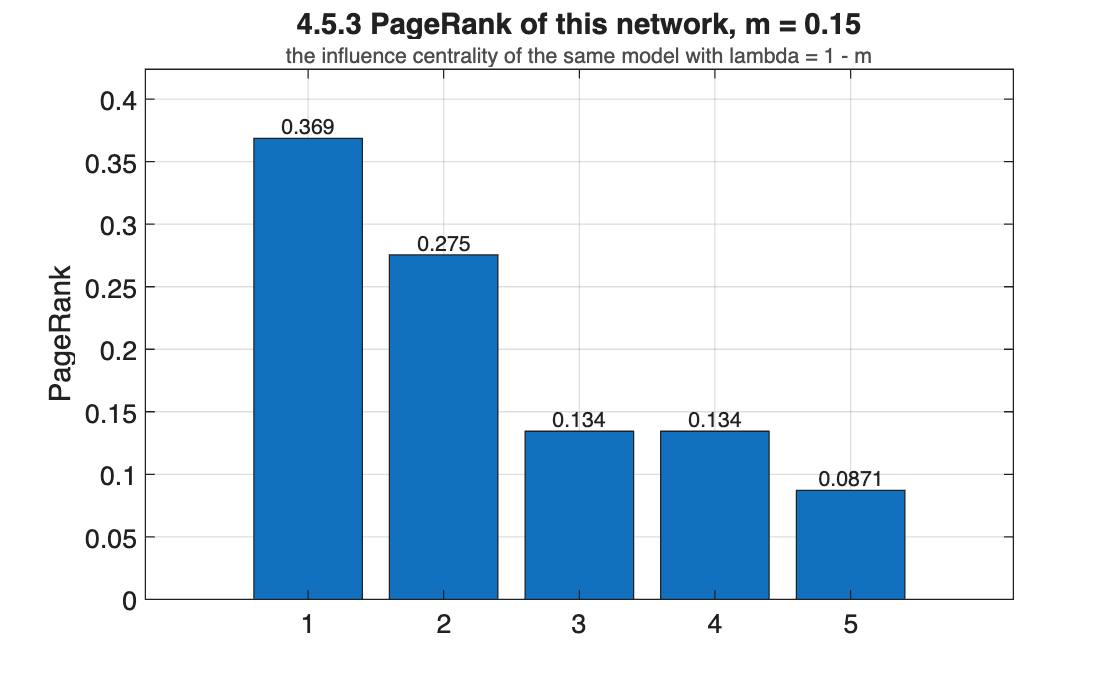


figure;
plot_bars(cpr, [], 'YLabel','PageRank', ...
    'Title','4.5.3 PageRank of this network, m = 0.15', ...
    'Subtitle','the influence centrality of the same model with lambda = 1 - m')

So the chain of the whole project closes here. Network structure fixes W; W and Lambda fix the dynamics; the dynamics fix V and with it the asymptotic influence of each agent; averaging that influence gives a centrality measure; and one member of that family, the one with lambda = 1 - m, is PageRank.